% Generate the figures for Cleve's Corner.
% "Magic" Reconstruction: Compressed Sensing.
% MathWorks News and Notes, Fall, 2010.
% Use "L1 magic" by Justin Romberg.
% http://www.acm.caltech.edu/l1magic 
% f = signal = tone from "1" key on touch tone phone.
% b = random subsample.

Source:

Article: [https://www.mathworks.com/company/newsletters/articles/magic-reconstruction-compressed-sensing.html](https://www.mathworks.com/company/newsletters/articles/magic-reconstruction-compressed-sensing.html)

code: [https://www.mathworks.com/matlabcentral/fileexchange/28250-generate-figures-for-cleve-s-corner-on-compressed-sensing](https://www.mathworks.com/matlabcentral/fileexchange/28250-generate-figures-for-cleve-s-corner-on-compressed-sensing)

clear all; close all;

Fs=8192;
Ts=1/Fs;
t=[0:Ts:1];
F_A=440; %Frequency of note A is 440 Hz
F_E=659.26; %Frequency of note E
F_Fbar = 739.99; %Frequency of note F#
F_D= 587.33; %Frequency of note D

A=sin(2*pi*F_A*t);
E=sin(2*pi*F_E*t);
Fbar=sin(2*pi*F_Fbar*t);
D=sin(2*pi*F_D*t);

song = [A,A,E,E,Fbar,Fbar,E,E,D,D];
sound(song,Fs);

cs_A = comp(A,t,10)';
cs_E = comp(E,t,10)';
cs_Fbar = comp(Fbar,t,10)';
cs_D = comp(D,t,10)';
cs_song = [cs_A,cs_A,cs_E,cs_E,cs_Fbar,cs_Fbar,cs_E,cs_E,cs_D,cs_D]

cs_song =     0.0000    0.3311    0.0092   -0.0958    0.1223    0.1380    0.1125   -0.0463   -0.1351    0.0453   -0.0285    0.2080   -0.1039   -0.3875   -0.1521    0.1192    0.0620   -0.0802   -0.3061   -0.1749    0.1749    0.7200    0.1905   -0.2998   -0.1115    0.8349    0.6055    0.1290   -0.2839   -0.1086    0.1797    0.2059   -0.0287   -0.3198   -0.3899    0.1468    0.0434   -0.0797   -0.0301   -0.1147    0.2296    0.2409    0.1889    0.0405   -0.1336    0.2177    0.0953   -0.0546   -0.1063   -0.2671


sound(cs_song,Fs);

# Visualizing what happened:

Let's try note A + E+D first:

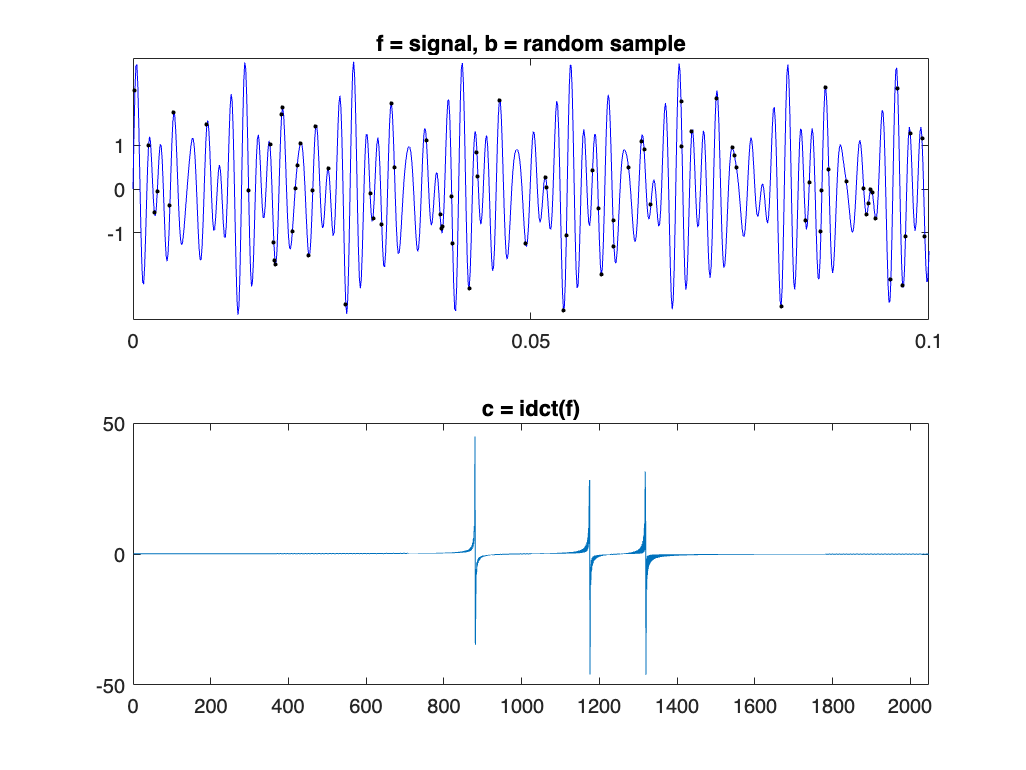

AED= sin(2*pi*F_A*t)+ sin(2*pi*F_E*t) + sin(2*pi*F_D*t);

f = AED';
t = t';

n = length(f);
m = ceil(n/10); %sampling rate
k = randperm(n)';
k = sort(k(1:m));
b = f(k);


% Plot f and b.
% Plot idct(f) = inverse discrete cosine transform.
axf = [0 max(t)/10 -3 3];
axd = [0 n/4 -50 50];

figure(1);
subplot(2,1,1)
plot(t,f,'b-',t(k),b,'k.')
axis(axf);
set(gca,'xtick',0:0.05:1,'ytick',-1:1)
title('f = signal, b = random sample')
subplot(2,1,2)
plot(idct(f))
axis(axd);
set(gca,'xtick',0:200:Fs)
title('c = idct(f)')

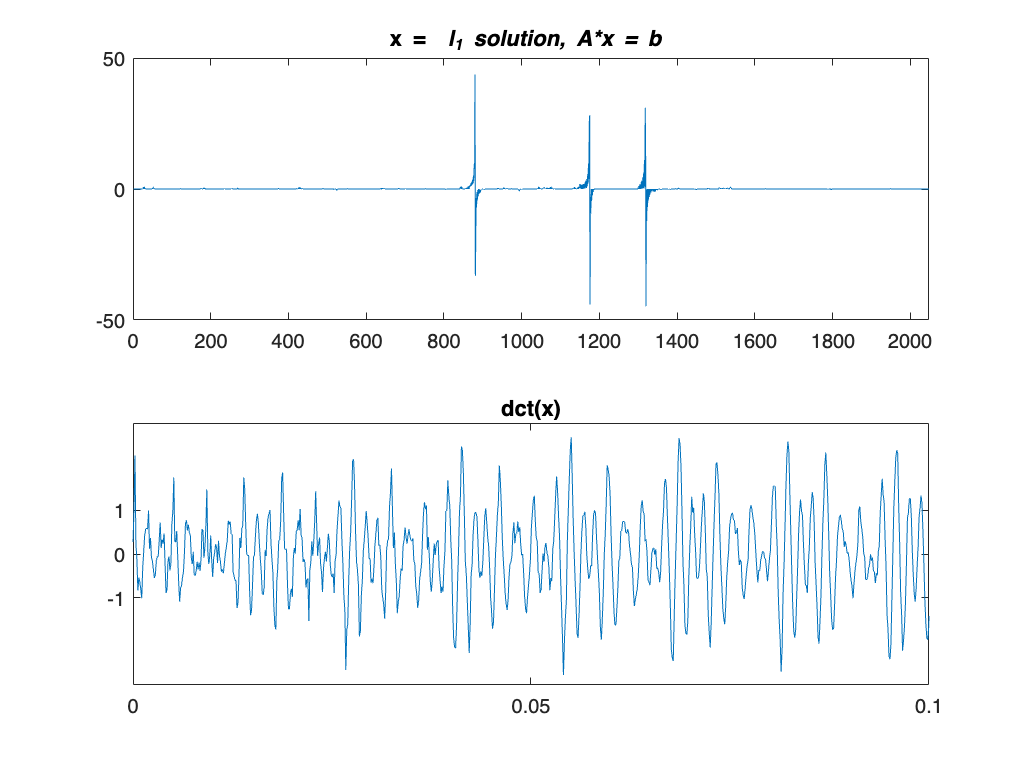

drawnow



% A = rows of DCT matrix with indices of random sample.
A = zeros(m,n);
for i = 1:m
   ek = zeros(1,n);
   ek(k(i)) = 1;
   A(i,:) = idct(ek);
end
% y = l_2 solution to A*y = b.
y = pinv(A)*b;
% x = l_1 solution to A*x = b.
% Use "L1 magic".
x = l1eq_pd(y,A,A',b,5e-3,32);
% Plot x and dct(x).
% Good comparison with f.

figure(2)
subplot(2,1,1)
plot(x)
axis(axd);
set(gca,'xtick',0:200:Fs)
title('x = {\it l}_1 solution, A*x = b ')
subplot(2,1,2)
plot(t,dct(x))
axis(axf);
set(gca,'xtick',0:.05:1,'ytick',-1:1)
title('dct(x)')

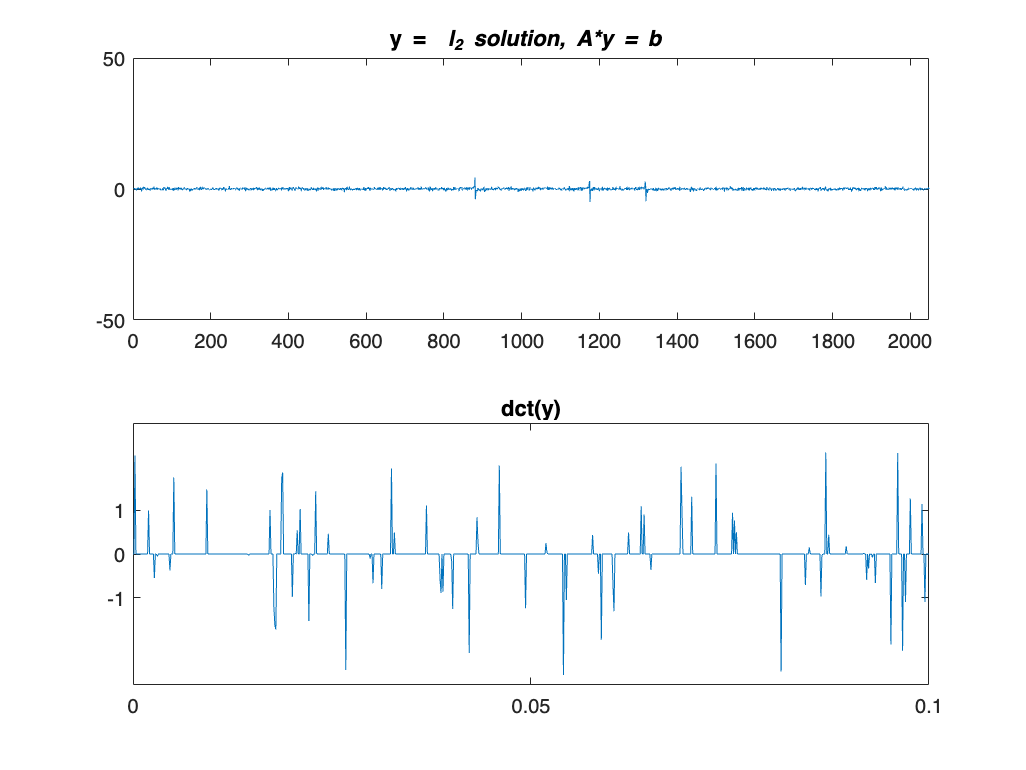

% Plot y and dct(y).
% Lousy comparison with f.



figure(3)
subplot(2,1,1)
plot(y)
axis(axd);
set(gca,'xtick',0:200:Fs)
title('y = {\it l}_2 solution, A*y = b ')
subplot(2,1,2)
plot(t,dct(y))
axis(axf);
set(gca,'xtick',0:.05:1,'ytick',-1:1)
title('dct(y)')

function f1 = comp(in,T,sr)
    f = in';
    t = T';
    
    n = length(f);
    m = ceil(n*sr/100); %sampling rate
    k = randperm(n)';
    k = sort(k(1:m));
    b = f(k);
    
    A = zeros(m,n);
    for i = 1:m
       ek = zeros(1,n);
       ek(k(i)) = 1;
       A(i,:) = idct(ek);
    end
    % y = l_2 solution to A*y = b.
    y = pinv(A)*b;
    % x = l_1 solution to A*x = b.
    % Use "L1 magic".
    x = l1eq_pd(y,A,A',b,5e-3,32);
    
    f1 = dct(x);
    f2 = dct(y);

end